# 模拟筛选法

## 序

clc;clear;clf;  % "我一无所有了。你可以重新来过啊！"

tic;    % 总计时-开始

%%% 加载储存颜色的 字符串数组
load('D:\M\bin\Moonwind\Color_23.mat');
%%%


## 预

% 定义全局变量
global ds start0 a c e dL dR L mark p0 alpha0 realx0 realy0 x_lim y_lim xx yy Noi;

a = 30; % 前轮立轴中心到凸轮内侧面的距离
c = 3;  % 凸轮厚
e = 4;  % 摆杆（滚子）直径
dL = 100; % 主动（左）后轮到前轮立杆横向距离
dR = 43;  % 从动（右）后轮到前轮立杆横向距离
L = 147.5;  % 前轮立轴到后轮轴的距离
p0 = 50; % 凸轮伪基圆半径p0
mark = -1;  % 标志变量mark——凸轮在左侧或右侧

%%% 目标点位集
targetP = [1500;550];
%%%

% 输出显示文本和数据
fprintf('|初始数据如下|')

|初始数据如下|

fprintf('— — — — — — — — — — — — — — — — — — — — — — — — —')   % 分割线

— — — — — — — — — — — — — — — — — — — — — — — — —

fprintf('1. 车身初始朝向（alpha0为车身纵轴线与y轴夹角）：%f°', alpha0 * 180 / pi);

1. 车身初始朝向（alpha0为车身纵轴线与y轴夹角）：90.000000°

fprintf('2. 主动（左后）轮初始位置坐标：(%d,%d)', realx0, realy0);

2. 主动（左后）轮初始位置坐标：(1.500066e+03,5.500387e+02)

## “模拟+筛选”（分段进行）

ds = 0.1;   % 行进步长ds

%%% 输出显示文本和数据
fprintf('3. 小车行进步长：%f mm', ds);

3. 小车行进步长：0.100000 mm

fprintf('————————————————————————————————————————————————')    % 分割线

————————————————————————————————————————————————

%%%


### 🦎第一段


% 数据预处理
Noi = 1; % 第一段编号
    % 初始点位数据
    alpha0 = pi / 180 * 90;  % 车身初始朝向
    realx0 = 2250;  realy0 = 0;  % 主动（左后）轮初始位置坐标
    start0 = 0; % 波程曲线 横坐标左起始点
    x_lim = [-2600, 2600];
    y_lim = [-2000, 2000];
    % 目标点位 数据处理
    targetP_x = targetP(1, Noi);    % 目标点位横坐标
    targetP_y = targetP(2, Noi);    % 目标点位纵坐标
    xx = targetP(1, 1);  yy = targetP(2, 1);

    % 给定筛选半径
        r0 = 100;   % 初筛半径


#### 初筛

% 初筛计时
tic;    % 初筛计时-开始
% 数据预处理
    s_start = 800;  s_end = 1400;   % 周期长 初筛始终范围
    A_start = 0;    A_end = 15;     % 振幅 初筛始终范围
    %%% 初筛数据个数
    ns = floor((s_end - s_start) / (2 * r0 / 3));   % 周期长筛选个数（由筛选半径决定）
    nA = 10;    % 振幅筛选个数 >>>（自主给定）
    %%%
%%% 初筛过程可视化
fig = figure(1);
hold on;
axis equal; % 将横轴纵轴的定标系数设成相同值
    % 锁定坐标轴显示范围
    xlim(x_lim);    % x轴显示范围
    ylim(y_lim);    % y轴显示范围
grid on;    % 显示网格背景
paint1();   % 绘制场地图
plot(xx, yy, 'ro'); % 使用红圈标记目标点位
counti = 1;
%%%

%%% 筛选开始……
fprintf("筛选进行中>>>>>>>>>>")

筛选进行中>>>>>>>>>>

while 1
    fprintf('第%d次筛选运算结果总个数（兼循环次数）：%d', counti, nA*ns);
    
    %%% 调用函数，进行此次筛选
    [min_s, max_s, min_A, max_A, h] = filter1(s_start, s_end, A_start, A_end, ns, nA, r0);
    %%%
    
    % 筛选结果对接
    s_start = min_s;    s_end = max_s;
    A_start = min_A;    A_end = max_A;
    
    r0 = 2 * r0 / (nA - 1); % 筛选半径缩小
    ns = floor((s_end - s_start) / (2 * r0 / 3));   % 周期长筛选个数（由筛选半径决定）
    
    %%% 判断是否结束初筛
    if r0 > 1   % 自动筛选
        delete(h{1});
        delete(h{3});
    else
        break;
    end
    counti = counti + 1;
end

第1次筛选运算结果总个数（兼循环次数）：90

第2次筛选运算结果总个数（兼循环次数）：150

第3次筛选运算结果总个数（兼循环次数）：140

第4次筛选运算结果总个数（兼循环次数）：150

#### 终筛

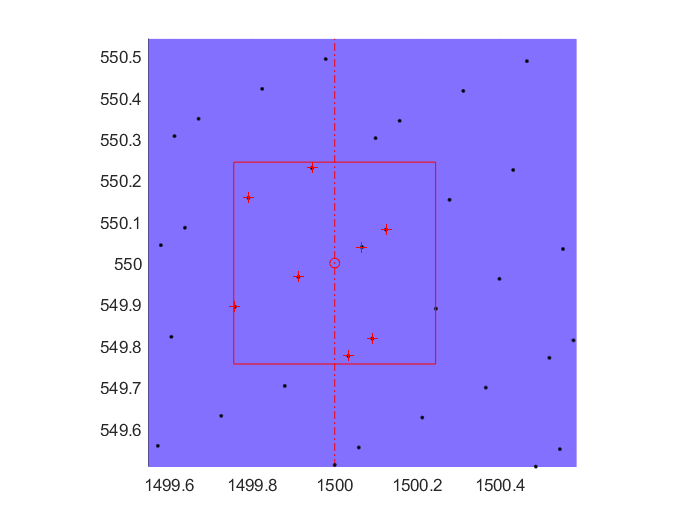

delete(h{1});
delete(h{3});
filter1(s_start, s_end, A_start, A_end, ns, nA, r0);

return;
filter2(s_start, s_end, A_start, A_end, ns, nA);

# 函数

#### 正弦函数段

function [dse, B] = sinf(A, Ts, ds, start)
T = Ts;
w = pi / T;
LP = start;
RP = LP + T;

N = LP:ds:RP;
%%% 注：此时元素个数为 n

N(end) = [];    % 弃旧尾
%%% 注：此时元素个数 -1，变为 n-1

dse = RP - N(end);  % 获取新尾


B = A * sin(w * (N - LP));

% subplot(2, 1, 1);
% hold on;
% plot([N, RP], [B, 0], 'b')
end

#### 初筛函数filter1()

function [min_s, max_s, min_A, max_A, h] = filter1(s_start, s_end, A_start, A_end, ns, nA, r)
% 全局变量
global ds start0 a c dL L alpha0 realx0 realy0 xx yy;

% 数据预处理
xv = [xx-r, xx+r, xx+r, xx-r, xx-r];
yv = [yy-r, yy-r, yy+r, yy+r, yy-r];
s = linspace(s_start, s_end, ns);
A = linspace(A_start,A_end,nA);
nB = floor(s / ds);    % 获取 某页各行上 的 有效元素个数为 n-1
    % 三维矩阵初始化
    cut_array_3D = ones(ns, 1, nA); % 三维矩阵 增1列用
    B_3D = zeros(ns, nB(end), nA, 'double') + nan;  % 三维矩阵-存储波程曲线函数值
    ds_3D = ds * ones(size(B_3D), 'double');    % 三维矩阵-存储实际行进步长距离

%%% 双重循环-获取上述两个三维矩阵
P = 1;  % 页号-振幅（初始化）
for index_A = A
    R = 1;  % 行号-周期长（初始化）
    for index_s = s
        
        % 调用函数，获取一对确定(s,A)下的 一行波程信息B
        [dse, B] = sinf(index_A, index_s, ds, start0);
        
        % 将此次内循获得的数据存入三维矩阵中
        ds_3D(R, (numel(B)), P) = dse;    % 三维步长矩阵换新尾
        B_3D(R, (1:numel(B)), P) = B;   % 将一行波程信息 存入三维矩阵中

        R = R + 1;  % 行号自增1，对应下一个 周期长
    end
    P = P + 1;  % 页号自增1，对应下一个 振幅
end
%%%

% 求 曲率半径
    % 左转使振幅为正值，右转为负值（以此判断小车左转还是右转）
if A_end > 0    
    rho_3D = L * a ./ B_3D - dL;    % 左转情况下求 曲率半径信息（三维矩阵）
else
    rho_3D = L * (a + c) ./ B_3D - dL;  % 右转情况下求 曲率半径信息（三维矩阵）
end


% 求 车身小段转向角dθ
dtheta_3D = ds_3D ./ rho_3D;    % 求得车身小段转向角信息（三维矩阵）
    % 求 各点对应的转向角（转向角累加矩阵）
    dtheta_3D = permute(dtheta_3D, [2, 1, 3]);  % 对三维矩阵dtheta_3D的维度进行转置
    dtheta_cum_3D = cumsum(dtheta_3D); % 对转置后的三维矩阵dtheta_3D进行按列累加（所得矩阵待转置）
        dtheta_3D = permute(dtheta_3D, [2, 1, 3]);  % 对三维矩阵dtheta_3D的维度进行还原
    dtheta_cum_3D = permute(dtheta_cum_3D, [2, 1, 3]);  % 对求和叠加得到的矩阵 进行维度转置

% 求 车身朝向角α
alpha_3D = alpha0 + dtheta_cum_3D;    % 求得车身朝向角信息（三维矩阵）
    % 添头（三维矩阵头部增加一列）
    alpha_3D = [alpha0*cut_array_3D, alpha_3D];    % 将初始转向角添在头部
    % 去尾
        %%% 创建逻辑数组 进行索引
        logical_array = ismissing(alpha_3D);
        logical_array = circshift(logical_array, -1, 2);
        logical_array(:, end, :) = true(ns, 1, nA);
        %%%
    alpha_3D(logical_array) = nan; % 去尾，删去每行最后一个有效元素（注：不是最后一个元素）
    alpha_3D(:, end, :) = [];   % 去尾（三维矩阵，删去因添头而多出的一列）

% 求 β角
beta_3D = alpha_3D + dtheta_3D; % 求得β角信息（三维矩阵）

% 求 小段弦长dl
dl_3D = rho_3D .* sin(dtheta_3D / 2) * 2;   % 求得小段弦长信息（三维矩阵）
    dl_3D(isnan(dl_3D)) = ds(1);  % 修改 由于无穷大的曲率半径ρ所导致的值为NAN的dl
    %%% 注：beta中的NAN值未被清除，所以dl_3D在此处产生的无用数据会在后面被抵消掉

% 求 小段坐标变化信息dx、dy
dx_3D = dl_3D .* cos(beta_3D);  % 小段横坐标变化值
dy_3D = dl_3D .* sin(beta_3D);  % 小段纵坐标变化值
    % 进行矩阵转置，以便对矩阵正确累加
    dx_3D = permute(dx_3D, [2, 1, 3]);  
    dy_3D = permute(dy_3D, [2, 1, 3]);
    % 进行矩阵累加（待转置）
    cumsum_dx_3D = cumsum(dx_3D);
    cumsum_dy_3D = cumsum(dy_3D);
        % 进行矩阵转置
        cumsum_dx_3D = permute(cumsum_dx_3D, [2, 1, 3]);
        cumsum_dy_3D = permute(cumsum_dy_3D, [2, 1, 3]);

% 求 模拟位置坐标集(realx,realy)
realx_3D = realx0 + cumsum_dx_3D;   % 模拟位置横坐标
realy_3D = realy0 + cumsum_dy_3D;   % 模拟位置纵坐标
    % 添头（三维矩阵头部增加一列）
    % 将初始位置坐标添加到头部（三维矩阵）
    realx_3D = [realx0*cut_array_3D, realx_3D];
    realy_3D = [realy0*cut_array_3D, realy_3D];
    
% 求 模拟位置 终点坐标集
    %%% 使用单循环 获取终点坐标 索引逻辑数组
    logical_array = ~logical_array;
    for i = 1:ns
        logical_array(i, 1:nB(i)-1, :) = false;
    end
    %%%
    
    % 终点坐标-但 一维数组
    realx_end = realx_3D(logical_array);
    realy_end = realy_3D(logical_array);
    % 终点坐标-但 二维矩阵
    realx_endP_2D = reshape(realx_end, [ns, nA]);
    realy_endP_2D = reshape(realy_end, [ns, nA]);

%%% 获取在筛选半径内模拟位置终点坐标集的 逻辑索引数组
in = inpolygon(realx_endP_2D, realy_endP_2D, xv, yv);   % 逻辑索引数组（二维）
%%% 获取符合筛选条件的 周期长和振幅 的 逻辑索引数组
in_s = logical(sum(in, 2));    % 逻辑索引数组-周期长
in_A = logical(sum(in, 1)); % 逻辑索引数组-振幅
%%%

%%% 绘制点的动态筛选过程
pause(1);   % （暂停1秒）1秒后再画出全部的点
    h1 = plot(realx_endP_2D, realy_endP_2D, 'k.');    % 画出全部的点
pause(1);   % （暂停1秒）1秒后缩小坐标轴范围，实现局部放大
    xlim([xx-10*r, xx+10*r]);
    ylim([yy-10*r, yy+10*r]);
pause(1);   % （暂停1秒）1秒后缩小坐标轴范围，再次局部放大
%     x_lim = [xx-5*r, xx+5*r];
%     y_lim = [yy-5*r, yy+5*r];
    xlim([xx-5*r, xx+5*r]);
    ylim([yy-5*r, yy+5*r]);
pause(1);   % （暂停1秒）1秒后再画出红框
    h2 = plot(xv, yv, 'r'); % 画出红框
pause(1);   % （暂停1秒）让红框停留一秒后再消失
    delete(h2); % 红框暂时消失
% plot(xv, yv, 'g');
pause(1)    % （暂停1秒）红框消失1秒，1秒后红框恢复
    plot(xv, yv, 'r');  % 红框恢复
pause(0.5); % （暂停0.5秒）0.5秒后用红十字标出位于红框中的点
    h3 = plot(realx_endP_2D(in), realy_endP_2D(in), 'r+'); % 用红十字标出位于红框中的点
pause(2);   % （暂停两秒），让可视化结果显示2秒后再消失
    h = {h1, h2, h3};
%%%

h4 = 

%%% >>>初筛结果数据返回
min_s = min(s(in_s));   max_s = max(s(in_s));
min_A = min(A(in_A));   max_A = max(A(in_A));
%%% >>>>>>

if isempty(min_s) || isempty(max_s) || isempty(min_A) || isempty(max_A) || ...
   (min_s == max_s) || (min_A == max_A)
    error("警告！！！请增大筛选个数（或需同时增大筛选半径）");
end

end

#### 终筛函数filter2()

function filter2(s_start, s_end, A_start, A_end, ns, nA)

%%% 加载储存颜色的 字符串数组
load('D:\M\bin\Moonwind\Color_23.mat');
%%%

% 全局变量
global ds start0 a c dL L alpha0 realx0 realy0 xx yy Noi;

s = linspace(s_start, s_end, ns);
A = linspace(A_start,A_end,nA);
nB = floor(s / ds);    % 获取 某页各行上 的 有效元素个数为 n-1
    % 三维矩阵初始化
    cut_array_3D = ones(ns, 1, nA); % 三维矩阵 增1列用
    B_3D = zeros(ns, nB(end), nA, 'double') + nan;  % 三维矩阵-存储波程曲线函数值
    ds_3D = ds * ones(size(B_3D), 'double');    % 三维矩阵-存储实际行进步长距离

%%% 双重循环-获取上述两个三维矩阵
P = 1;  % 页号-振幅（初始化）
for index_A = A
    R = 1;  % 行号-周期长（初始化）
    for index_s = s
        
        % 调用函数，获取一对确定(s,A)下的 一行波程信息B
        [dse, B] = sinf(index_A, index_s, ds, start0);
        
        % 将此次内循获得的数据存入三维矩阵中
        ds_3D(R, (numel(B)), P) = dse;    % 三维步长矩阵换新尾
        B_3D(R, (1:numel(B)), P) = B;   % 将一行波程信息 存入三维矩阵中

        R = R + 1;  % 行号自增1，对应下一个 周期长
    end
    P = P + 1;  % 页号自增1，对应下一个 振幅
end
%%%

% 求 曲率半径
    % 左转使振幅为正值，右转为负值（以此判断小车左转还是右转）
if A_end > 0    
    rho_3D = L * a ./ B_3D - dL;    % 左转情况下求 曲率半径信息（三维矩阵）
else
    rho_3D = L * (a + c) ./ B_3D - dL;  % 右转情况下求 曲率半径信息（三维矩阵）
end


% 求 车身小段转向角dθ
dtheta_3D = ds_3D ./ rho_3D;    % 求得车身小段转向角信息（三维矩阵）
    % 求 各点对应的转向角（转向角累加矩阵）
    dtheta_3D = permute(dtheta_3D, [2, 1, 3]);  % 对三维矩阵dtheta_3D的维度进行转置
    dtheta_cum_3D = cumsum(dtheta_3D); % 对转置后的三维矩阵dtheta_3D进行按列累加（所得矩阵待转置）
        dtheta_3D = permute(dtheta_3D, [2, 1, 3]);  % 对三维矩阵dtheta_3D的维度进行还原
    dtheta_cum_3D = permute(dtheta_cum_3D, [2, 1, 3]);  % 对求和叠加得到的矩阵 进行维度转置

% 求 车身朝向角α
alpha_3D = alpha0 + dtheta_cum_3D;    % 求得车身朝向角信息（三维矩阵）
    % 添头（三维矩阵头部增加一列）
    alpha_3D = [alpha0*cut_array_3D, alpha_3D];    % 将初始转向角添在头部
    % 去尾
        %%% 创建逻辑数组 进行索引
        logical_array = ismissing(alpha_3D);
        logical_array = circshift(logical_array, -1, 2);
        logical_array(:, end, :) = true(ns, 1, nA);
        %%%
    alpha_3D(logical_array) = nan; % 去尾，删去每行最后一个有效元素（注：不是最后一个元素）
    alpha_3D(:, end, :) = [];   % 去尾（三维矩阵，删去因添头而多出的一列）

% 求 β角
beta_3D = alpha_3D + dtheta_3D; % 求得β角信息（三维矩阵）

% 求 小段弦长dl
dl_3D = rho_3D .* sin(dtheta_3D / 2) * 2;   % 求得小段弦长信息（三维矩阵）
    dl_3D(isnan(dl_3D)) = ds(1);  % 修改 由于无穷大的曲率半径ρ所导致的值为NAN的dl
    %%% 注：beta中的NAN值未被清除，所以dl_3D在此处产生的无用数据会在后面被抵消掉

% 求 小段坐标变化信息dx、dy
dx_3D = dl_3D .* cos(beta_3D);  % 小段横坐标变化值
dy_3D = dl_3D .* sin(beta_3D);  % 小段纵坐标变化值
    % 进行矩阵转置，以便对矩阵正确累加
    dx_3D = permute(dx_3D, [2, 1, 3]);  
    dy_3D = permute(dy_3D, [2, 1, 3]);
    % 进行矩阵累加（待转置）
    cumsum_dx_3D = cumsum(dx_3D);
    cumsum_dy_3D = cumsum(dy_3D);
        % 进行矩阵转置
        cumsum_dx_3D = permute(cumsum_dx_3D, [2, 1, 3]);
        cumsum_dy_3D = permute(cumsum_dy_3D, [2, 1, 3]);

% 求 模拟位置坐标集(realx,realy)
realx_3D = realx0 + cumsum_dx_3D;   % 模拟位置横坐标
realy_3D = realy0 + cumsum_dy_3D;   % 模拟位置纵坐标
    % 添头（三维矩阵头部增加一列）
    % 将初始位置坐标添加到头部（三维矩阵）
    realx_3D = [realx0*cut_array_3D, realx_3D];
    realy_3D = [realy0*cut_array_3D, realy_3D];
    
% 求 模拟位置 终点坐标集
    %%% 使用单循环 获取终点坐标 索引逻辑数组
    logical_array = ~logical_array;
    for i = 1:ns
        logical_array(i, 1:nB(i)-1, :) = false;
    end
    %%%
    
    % 终点坐标-但 一维数组
    realx_end = realx_3D(logical_array);
    realy_end = realy_3D(logical_array);
    % 终点坐标-但 二维矩阵
    realx_endP_2D = reshape(realx_end, [ns, nA]);
    realy_endP_2D = reshape(realy_end, [ns, nA]);
    
    % 终点坐标偏心距eccentric_distance-但一维数组
    ed_2D = sqrt((realx_endP_2D - xx) .^ 2 + (realy_endP_2D - yy) .^ 2);

% 索引数组
[in_R, in_C] = find(ed_2D == min(min(ed_2D)));

realx = realx_3D(in_R, :, in_C);
realy = realy_3D(in_R, :, in_C);

realx0 = realx_endP_2D(in_R, in_C);
realy0 = realy_endP_2D(in_R, in_C);


figure(2)
hold on;
axis equal;
grid on;
paint1();
plot(xx, yy, 'ro')
plot(realx, realy, '.', 'Color', Color_23(Noi * 3));


end

### 场地图绘制函数paint1()

function paint1()
rectangle('position',[-2600,-1100,5200,2200]);%场地边框
rectangle('position',[-2100,-550,4200,1100],'curvature',1,'Linestyle','-.');%立桩所在曲线
%立桩位置
rectangle('position',[2090,-10,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[1490,540,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[1490,-560,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[490,540,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[490,-560,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[-510,540,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[-510,-560,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[-1510,540,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[-1510,-560,20,20],'curvature',[1,1],'facecolor','#8470FF');
rectangle('position',[-2110,-10,20,20],'curvature',[1,1],'facecolor','#8470FF');
%挡板位置
plot([-1500,-500],[0,0],'r',[500,1500],[0,0],'r','linewidth',2);
%随机桩位挡板
plot([200,800],[550,550],'m',[-200,-800],[550,550],'m',[200,800],[-550,-550],'m',[-200,-800],[-550,-550],'m','linewidth',2);
%中心轴线
plot([0,0],[-1300,1300],'k-.',[-2800,2800],[0,0],'k-.');
%构造线
plot([1500,1500],[200,1000],'r-.',[500,500],[200,1000],'r-.');
plot([1500,1500],[-200,-1000],'r-.',[500,500],[-200,-1000],'r-.');
plot([-1500,-1500],[200,1000],'r-.',[-500,-500],[200,1000],'r-.');
plot([-1500,-1500],[-200,-1000],'r-.',[-500,-500],[-200,-1000],'r-.');
plot([2000,2000],[-100,100],'r-.',[-2000,-2000],[-100,100],'r-.');
plot([1900,1900],[-100,100],'b-.',[-1900,-1900],[-100,100],'b-.');
plot([2100,2100],[-300,300],'y');
end